rng(2018)
r = rand(1,2)*2*pi;
%%below angles are in radians
theta_A = r(1,1);
theta_B = r(1,2);
%convert to degrees
theta_A = theta_A * (180 / pi);
theta_B = theta_B * (180 / pi);
%parameters
mu1 = [(5 / (tand(360 - theta_A))); 0];
mu0 = [(5 / (tand(360 - theta_A))); -5];
sigma1 = [cosd(theta_B), -sind(theta_B) ; sind(theta_B), cosd(theta_B)]*...
    [4,0;0,1]*[cosd(theta_B), -sind(theta_B); sind(theta_B), cosd(theta_B)]';
sigma0 = sigma1;

%ideal weight vector would be w = [((sigma1)^-1)*(mu1-mu0)]
idealw = [((sigma1)^-1)*(mu1-mu0)];

%create training dataset (dstrain)
dstrain = prtDataGenUnimodal(100,mu0,mu1,sigma0,sigma1);
plot(dstrain)
hold on
%Caculate new (non-ideal) w vector
dataH0 = dstrain.getObservationsByClassInd(1);
dataH1 = dstrain.getObservationsByClassInd(2);
x0 = mean(dataH0);
x1 = mean(dataH1);
Sw = cov(dataH0) + cov(dataH1);
Sb = (x1 - x0)*(x1 - x0)';
% lambda = ((Sw)^-1)*Sb;
% w = ((Sw)^-1)*(x1-x0)';
% wlambda = lambda * w;
% plot(wlambda)
plot(idealw)
% hold on
% fld = prtClassFld;
% fld = fld.train(dstrain)

fld =   prtClassFld with properties:

                    name: 'Fisher Linear Discriminant'
        nameAbbreviation: 'FLD'
            isNativeMary: 0
                       w: [2×1 double]
               plotBasis: 0
         plotProjections: 0
        twoClassParadigm: 'binary'
         internalDecider: []
            isSupervised: 1
    isCrossValidateValid: 1
          verboseStorage: 1
         showProgressBar: 1
               isTrained: 1
          dataSetSummary: [1×1 struct]
                 dataSet: [1×1 prtDataSetClass]
                userData: [1×1 struct]


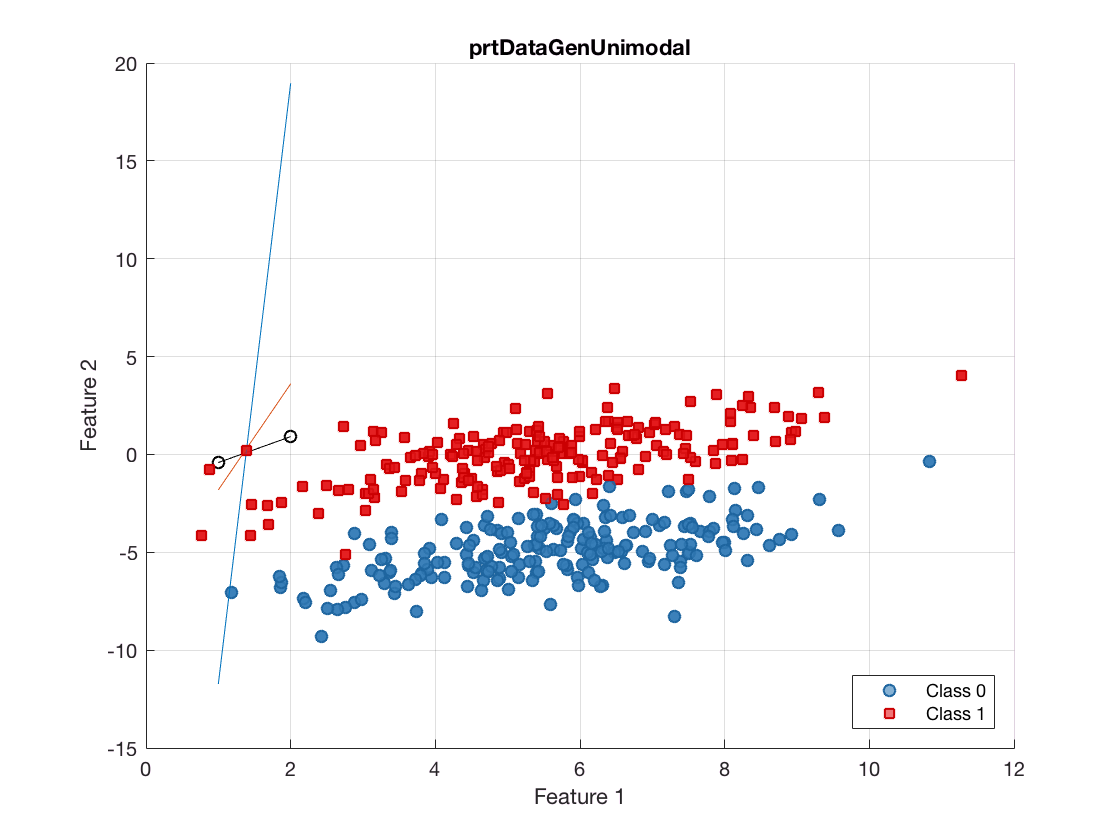

% plot(fld.w,'ko')

% 
%create testing dataset (dstest)
dstest = prtDataGenUnimodal(100,mu0,mu1,sigma0,sigma1);
plot(dstest)


%create classifier,test, and display ROC results
%Everything from here below is complete trash and just a shell

classifier = (wlambda);
classifier = classifier.train(dstrain);

Struct contents reference from a non-struct array object.

classified = classifier.run(dstest);
results = classified;
prtScoreRoc(results);
prtScorePercentCorrect(results);
